node = [1,0; 1,1; 0,1; -1,1; -1,0; -1,-1; 0,-1; 0,0];  % coordinates
elem = [1,2,8; 3,8,2; 8,3,5; 4,5,3; 7,8,6; 5,6,8];     % connectivity
showmesh(node,elem); 
axis on;

findelem(node,elem);  % plot indices of all triangles
% findnode(node);       % plot indices of all vertices

help showmesh

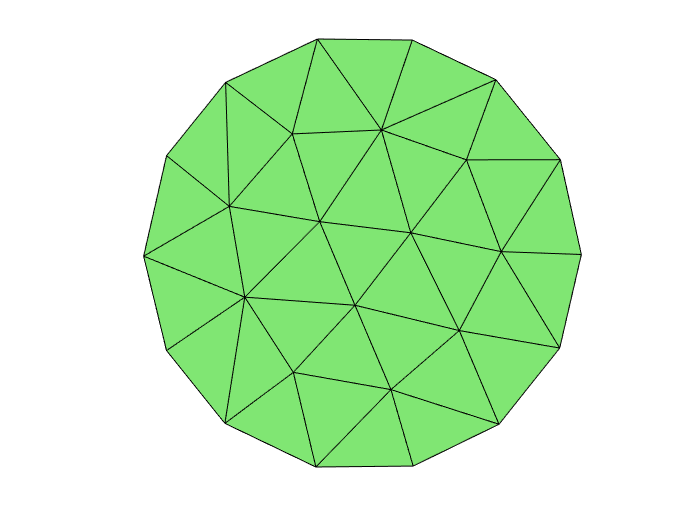

ans =   Patch with properties:

    FaceColor: [0.5000 0.9000 0.4500]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [36×3 double]
     Vertices: [26×3 double]

  Show all properties


 - Min quality 0.79
 - Mean quality 0.95
 - Uniformity 5.0%
 


fd=@(p) sqrt(sum(p.^2,2))-1; % 距离函数 确定所需要的区域
[p,t]=distmesh2d(fd,@huniform,0.3,[-1,-1;1,1],[]); % p 每个顶点的坐标 t(N*3) N个三角形对应的顶点标号

showmesh(p,t)

ans =   Patch with properties:

    FaceColor: [0.5000 0.9000 0.4500]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [36×3 double]
     Vertices: [26×3 double]

  Show all properties


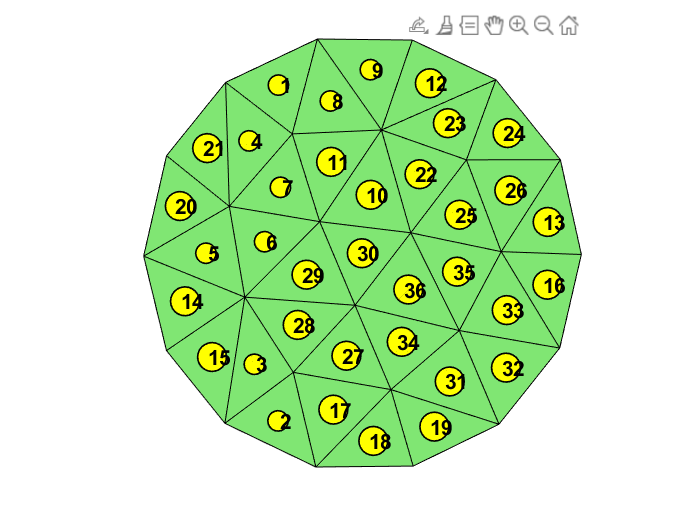

% findelem(p,t);  % plot indices of all triangles

% findnode(p);       % plot indices of all vertices

% for i = 1:2
%     [node,elem] = uniformrefine(node,elem);

% end
% showmesh(node,elem);

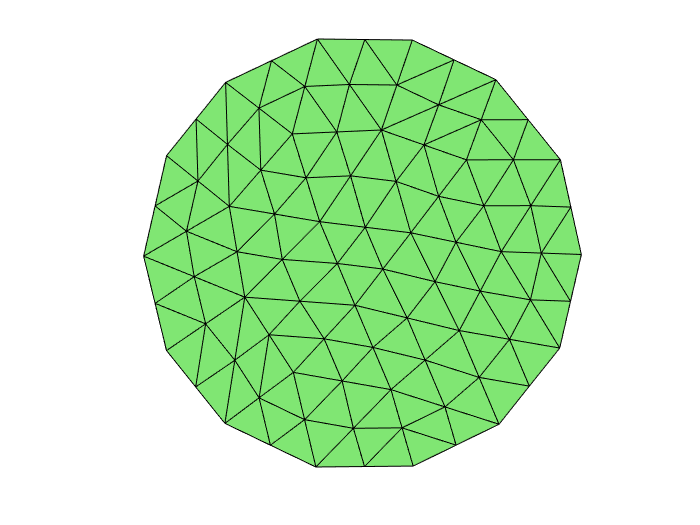

ans =   Patch with properties:

    FaceColor: [0.5000 0.9000 0.4500]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [144×3 double]
     Vertices: [87×3 double]

  Show all properties



[p1,t1] = uniformrefine(p,t);
showmesh(p1,t1)

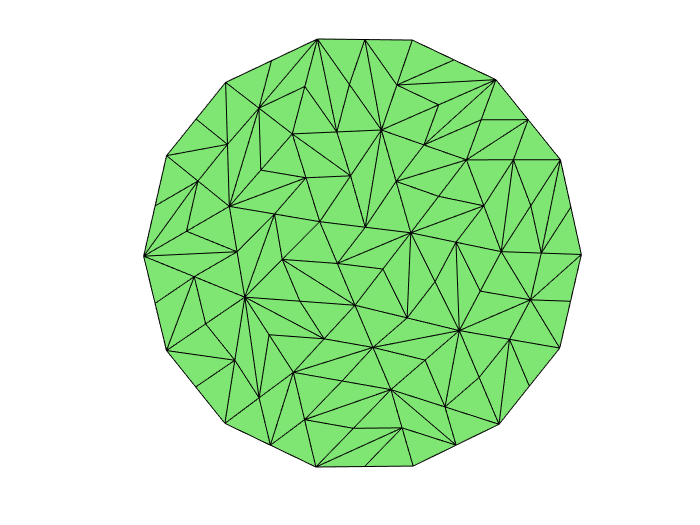

ans =   Patch with properties:

    FaceColor: [0.5000 0.9000 0.4500]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [144×3 double]
     Vertices: [87×3 double]

  Show all properties


[p2,t2] = uniformbisect(p,t);
showmesh(p2,t2)

node = [0,0; 1,0; 1,1; 0,1];
elem = [2,3,1; 4,1,3];
figure(1); subplot(1,3,1); showmesh(node,elem);
[node,elem] = uniformrefine(node,elem);
figure(1); subplot(1,3,2); showmesh(node,elem);
bdFlag = setboundary(node,elem,'Dirichlet','all','Neumann','y==1');
[node,elem,bdFlag] = uniformrefine(node,elem,bdFlag);
figure(1); subplot(1,3,3); showmesh(node,elem);

help setboundary

node = [0,0; 1,0; 1,1; 0,1];
elem = [2,3,1; 4,1,3];
bdFlag = setboundary(node,elem,'Dirichlet','all','Neumann','y==1');
[node,elem,bdFlag] = uniformbisect(node,elem,bdFlag);
[node,elem,bdFlag] = uniformbisect(node,elem,bdFlag);
showmesh(node,elem);

allEdge = [elem(:,[2,3]); elem(:,[3,1]); elem(:,[1,2])];
Dirichlet = allEdge((bdFlag(:) == 1),:);
Neumann = allEdge((bdFlag(:) == 2) | (bdFlag(:) == 3),:);

findedge(node,Dirichlet,[],'noindex','LineWidth',4,'Color','r');

findedge(node,Neumann,[],'noindex','LineWidth',4,'Color','b');

help findedge

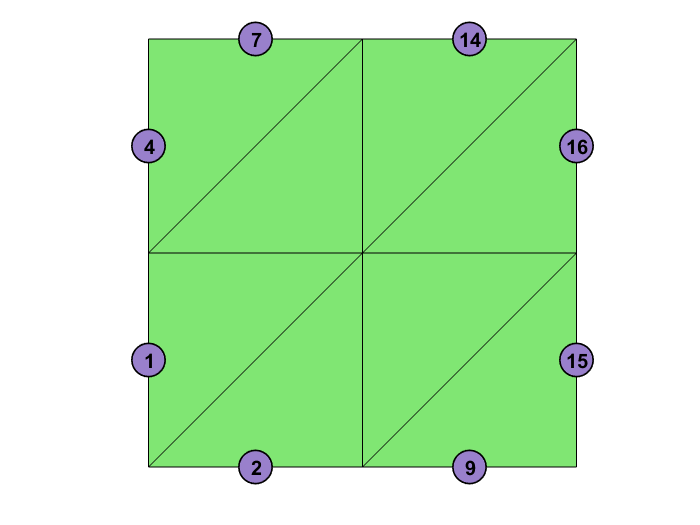

[node,elem] = squaremesh([0 1 0 1],0.5);
totalEdge = sort([elem(:,[2,3]); elem(:,[3,1]); elem(:,[1,2])],2);
[i,j,s] = find(sparse(totalEdge(:,2),totalEdge(:,1),1));
edge = [j,i]; 
bdEdge = [j(s==1),i(s==1)];
showmesh(node,elem);
findedge(node,edge,s==1);